Simulated Swarm stuff

load('pathdata.mat');

%[leader_pos_store, leader_vel_store, agent_pos_store, agent_vel_store] = interactive_simulation()

num_agents = 2;
p = zeros(num_agents, 2);
v = zeros(num_agents, 2);
p_leader_current = [-4, 0];
v_leader_current = [-4, 0];

x_pos = leader_pos_store(:,1)'

x_pos =    -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -4.0000   -3.9998   -3.9767   -3.9196   -3.8596   -3.7996   -3.7396   -3.6796   -3.6196   -3.5596   -3.4996   -3.4396   -3.3796   -3.3196   -3.2596   -3.1996   -3.1454   -3.0943   -3.0463   -3.0016   -2.9573   -2.9130   -2.8687   -2.8245   -2.7802   -2.7359   -2.6942   -2.6560   -2.6208   -2.5901   -2.5627   -2.5353   -2.5079   -2.4825   -2.4607   -2.4394


y_pos = leader_pos_store(:,2)'

y_pos =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000   -0.0002   -0.0102   -0.0242   -0.0362   -0.0451   -0.0530   -0.0590   -0.0651   -0.0705   -0.0743   -0.0754   -0.0749   -0.0717   -0.0571   -0.0251    0.0098    0.0477    0.0897    0.1318    0.1738    0.2158    0.2579    0.2999    0.3419    0.3865    0.4349    0.4863    0.5412    0.5996    0.6580    0.7165    0.7755    0.8355    0.8955



x_vel = leader_vel_store(:,1)'

x_vel =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0002    0.0230    0.0571    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0542    0.0511    0.0481    0.0447    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0417    0.0382    0.0352    0.0307    0.0274    0.0274    0.0274    0.0254    0.0219    0.0213


y_vel = leader_vel_store(:,1)'

y_vel =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0002    0.0230    0.0571    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0600    0.0542    0.0511    0.0481    0.0447    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0417    0.0382    0.0352    0.0307    0.0274    0.0274    0.0274    0.0254    0.0219    0.0213



num_steps = 130;

for i = 1:num_agents
    eval(sprintf('p_%d = [0; 0];', i));
    eval(sprintf('v_%d = [0; 0];', i));
end

p_1 = [-5; -1];
p_2 = [-5; 1];
%p_3 = [0; -2];
p = [p_1'; p_2'];

collision_count = 0;

for i = 1:num_steps
    N = neighbor_calc(p, num_agents);
    v = agent_velocity(N, p, v, p_leader_current, v_leader_current, num_agents);
    p = position_update(p, v);
    
    for j = 1:num_agents
            eval(sprintf('p_%d(:, end+1) = p(%d, :)'';', j, j)); 
            eval(sprintf('v_%d(:, end+1) = v(%d, :)'';', j, j));
    end

    p_leader_current = [x_pos(i), y_pos(i)];
    v_leader_current = [x_vel(i), y_vel(i)];

    collision_radius = 0.05;
    collisions = check_collisions(p, collision_radius);
    if any(collisions(:))
        collision_count = collision_count + 1;
    end
end

disp(['Total Collision Count: ', num2str(collision_count)]);

Total Collision Count: 0


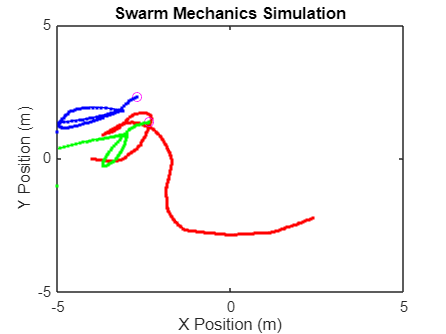


figure;
plot(x_pos, y_pos, 'r.-'); 
hold on;
for i = 1:num_agents
    plot(p(i, 1), p(i, 2), 'mo'); 
    plot(p_1(1, :), p_1(2, :), 'g.-');
    plot(p_2(1, :), p_2(2, :), 'b.-');
    %plot(p_3(1, :), p_3(2, :), 'c.-')
end
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([-5, 5, -5, 5]);
title('Swarm Mechanics Simulation');

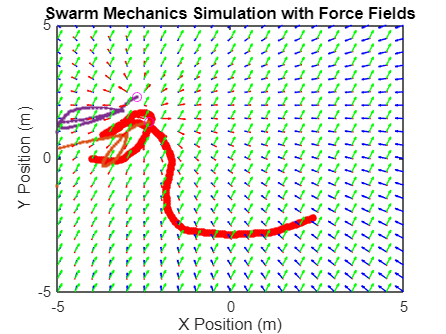

% Parameters for the forces
k_c = 0.05;     % cohesion
k_a = 0.1;      % alignment
k_s = 0.8;      % separation
r_0 = 0.9;      % avoidance range
k_avoid = 0.8;  % repulsion strength

% Grid of hypothetical positions for agent 1
[x_grid, y_grid] = meshgrid(-5:0.5:5, -5:0.5:5);
u_sep = zeros(size(x_grid));  % Separation force (x-component)
v_sep = zeros(size(y_grid));  % Separation force (y-component)

u_coh = zeros(size(x_grid));  % Cohesion force (x-component)
v_coh = zeros(size(y_grid));  % Cohesion force (y-component)

u_align = zeros(size(x_grid));  % Alignment force (x-component)
v_align = zeros(size(y_grid));  % Alignment force (y-component)

% Agent 1's current position and velocity
p1 = p(1, :);  % Position of agent 1
v1 = v(1, :);  % Velocity of agent 1

% Compute forces at each grid point
% Compute forces at each grid point
for ix = 1:size(x_grid, 1)
    for iy = 1:size(y_grid, 2)
        hypothetical_pos = [x_grid(ix, iy), y_grid(ix, iy)];

        % Initialize force components for each grid point
        F_sep = zeros(1, 2);
        F_coh = zeros(1, 2);
        F_align = zeros(1, 2);
        
        % Iterate through all agents to calculate separation, cohesion, and alignment
        for i = 1:num_agents
            % Separation Force (Avoidance)
            r_vec = hypothetical_pos - p(i, :);  % Vector from agent i to hypothetical position
            r = norm(r_vec);  % Distance
            F_sep = F_sep + k_s * (r_vec / r) * log(1 + r_0 / r);
                
            % Cohesion Force (Attraction to neighbors)
            F_coh = F_coh + k_c * (p(i, :) - hypothetical_pos);
                
            % Alignment Force (Align with neighbors)
            F_align = F_align + k_a * (v(i, :) - v1);
        end
        
        % Store the computed forces
        u_sep(ix, iy) = F_sep(1);
        v_sep(ix, iy) = F_sep(2);

        u_coh(ix, iy) = F_coh(1);
        v_coh(ix, iy) = F_coh(2);

        u_align(ix, iy) = F_align(1);
        v_align(ix, iy) = F_align(2);
    end
end

% Main Plot for the Swarm Simulation
figure;

% Plot the positions of the agents
plot(x_pos, y_pos, 'r.-', "MarkerSize", 15); 
hold on;

% Plot the positions and trajectories of the agents
for i = 1:num_agents
    % Ensure each agent's position is plotted, including agent 2 (p_2)
    eval(sprintf('plot(p_%d(1,:), p_%d(2,:), ''.-'');', i, i));  % Plot the trajectory
    plot(p(i, 1), p(i, 2), 'mo'); % Plot the current position
end

% Overlay the force fields as quiver plots
quiver(x_grid, y_grid, u_sep, v_sep, 'r', 'AutoScaleFactor', 0.5);   % Separation
quiver(x_grid, y_grid, u_coh, v_coh, 'b', 'AutoScaleFactor', 0.5);   % Cohesion
quiver(x_grid, y_grid, u_align, v_align, 'g', 'AutoScaleFactor', 0.5); % Alignment

% Labeling and formatting
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis([-5, 5, -5, 5]);
title('Swarm Mechanics Simulation with Force Fields');

hold off;

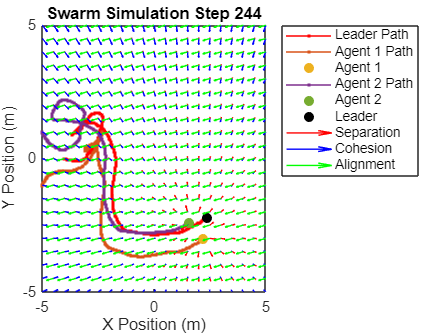

Illegal use of reserved keyword "end".

load('pathdata.mat');

num_agents = 2;
num_steps = length(x_pos);

% Leader path
x_pos = leader_pos_store(:,1)';
y_pos = leader_pos_store(:,2)';
x_vel = leader_vel_store(:,1)';
y_vel = leader_vel_store(:,2)';

% Initialize agent positions and velocities
p = [-5, -1; -5, 1];  % Each row is an agent
v = zeros(num_agents, 2);

% Store agent trajectories
agent_pos_history = cell(num_agents, 1);
for i = 1:num_agents
    agent_pos_history{i} = zeros(num_steps, 2);
    agent_pos_history{i}(1, :) = p(i, :);
end

  k_c = 0.01;     % cohesion
    k_a = 0.01;     % alignment
    k_s = 1.0;      % separation
    k_p = 0.05;     % attraction to leader position
    k_v = 1.8;     % attraction to leader velocity
    r_0 = 0.9;      % seperation influence radius
    dt = 0.05;      % time step for velocity integration
    v_max = 1.0; 
% Grid for force field
[x_grid, y_grid] = meshgrid(-5:0.5:5, -5:0.5:5);

figure;

for step = 1:num_steps
    clf; % Clear figure each frame

    % Update leader
    p_leader_current = [x_pos(step), y_pos(step)];
    v_leader_current = [x_vel(step), y_vel(step)];

    % Swarm logic
    N = neighbor_calc(p, num_agents);
    v = agent_velocity(N, p, v, p_leader_current, v_leader_current, num_agents);
    p = position_update(p, v);

    % Update agent history
    for i = 1:num_agents
        agent_pos_history{i}(step, :) = p(i, :);
    end

    % Compute forces
    u_sep = zeros(size(x_grid)); v_sep = zeros(size(y_grid));
    u_coh = zeros(size(x_grid)); v_coh = zeros(size(y_grid));
    u_align = zeros(size(x_grid)); v_align = zeros(size(y_grid));
    u_leader = zeros(size(x_grid)); v_leader = zeros(size(y_grid));

for ix = 1:size(x_grid, 1)
    for iy = 1:size(y_grid, 2)
        hypothetical_pos = [x_grid(ix, iy), y_grid(ix, iy)];
        F_sep = zeros(1, 2);
        F_coh = zeros(1, 2);
        F_align = zeros(1, 2);
        F_leader = zeros(1, 2);

        for i = 1:num_agents
            r_vec = hypothetical_pos - p(i, :);
            r = norm(r_vec);
            if r ~= 0
                % Separation from agents
                F_sep = F_sep + k_s * (r_vec / r) * log(1 + r_0 / r);
            end
            % Cohesion toward agents
            F_coh = F_coh + k_c * (p(i, :) - hypothetical_pos);

            % Alignment with agents (relative to agent 1)
            F_align = F_align + k_a * (v(i, :) - v(1, :));
        end

        % --- Leader force logic ---
        r_vec_leader = hypothetical_pos - p_leader_current;
        r_leader = norm(r_vec_leader);

        if r_leader ~= 0
            % Attraction to leader position
            F_leader = F_leader + k_p * r_vec_leader;

            % Repulsion from leader if too close
            if r_leader < r_0
                separation_from_leader_strength = k_s * (1/r_leader - 1/r_0);
                F_leader = F_leader + separation_from_leader_strength * (-r_vec_leader / r_leader);
            end
        end

        % --- Store force components ---
        u_sep(ix, iy) = F_sep(1);
        v_sep(ix, iy) = F_sep(2);
        u_coh(ix, iy) = F_coh(1);
        v_coh(ix, iy) = F_coh(2);
        u_align(ix, iy) = F_align(1);
        v_align(ix, iy) = F_align(2);
        u_leader(ix, iy) = F_leader(1);
        v_leader(ix, iy) = F_leader(2);
    end
end


    % Plot leader trajectory
    plot(x_pos(1:step), y_pos(1:step), 'r.-', 'DisplayName', 'Leader Path'); 
    hold on;

    % Plot agent paths and current positions
    for i = 1:num_agents
        traj = agent_pos_history{i};
        plot(traj(1:step, 1), traj(1:step, 2), '.-', 'DisplayName', sprintf('Agent %d Path', i));
        plot(p(i, 1), p(i, 2), '.', 'DisplayName', sprintf('Agent %d', i), "Markersize", 20);
    end

    % Plot leader's current position
    plot(p_leader_current(1), p_leader_current(2), 'k.', 'MarkerSize', 20, 'MarkerFaceColor', 'k', 'DisplayName', "Leader");

    % Plot force vector fields
    quiver(x_grid, y_grid, u_sep, v_sep, 'r', 'AutoScaleFactor', 0.8, 'DisplayName', "Separation");
    quiver(x_grid, y_grid, u_coh, v_coh, 'b', 'AutoScaleFactor', 0.8, 'DisplayName', "Cohesion");
    quiver(x_grid, y_grid, u_align, v_align, 'g', 'AutoScaleFactor', 0.8, 'DisplayName', "Alignment");
    quiver(x_grid, y_grid, u_leader, v_leader, 'k', 'AutoScaleFactor', 0.8, 'DisplayName', "Leader");

    xlabel('X Position (m)');
    ylabel('Y Position (m)');
    axis([-5, 5, -5, 5]);
    title(['Swarm Simulation Step ' num2str(step)]);
    legend('Location', 'northeastoutside');
    drawnow;
    pause(0.05); % Adjust for speed
end